# Gauss Seidel Solution to Load Flow

**SCHOOL OF ELECTRICAL AND ELECTRONIC ENGINEERING**

**Bachelor of Engineering (Hons) BE in Elect/Cont/Comm/Comp Eng**

**Program Code: (DT021A)**

**<YEAR 4>**

**Name of Module: (Power System Analysis, POWS4601)**

     **Student Name:   __****Talha Tallat, D18124645 ****___**

     **Academic Lecturer:  __*****Jane Courtney*****_______**

     **Submission Date:    __****1st November 2021____**

**1. Objectives Preparation:**

The purpose of this assignment is to analyze and solve the load flow system as given below in Figure 1 using the Gauss-Seidel method in Mathlab. This Matlab code provided is modified to analyze the power flow of the system as shown in Figure 1.

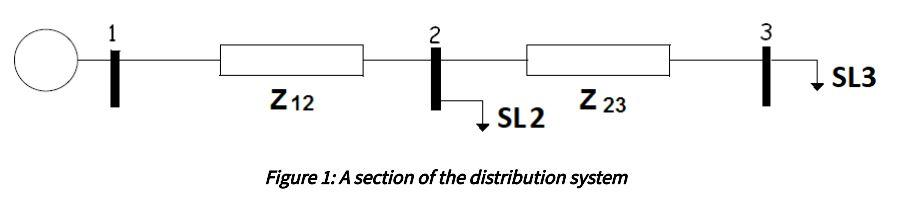

Bus and Line information is provided in the following tables to find the solution of the load flow system, where Bus 1 is the slack bus. Bus information is given in Table 1 and the line information is in given Table 2  and all values are in p.u. on a 10MVA base.

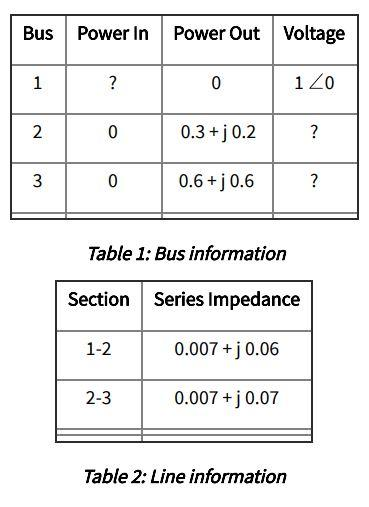

**2. Output:**

This Matlab program code 'Gauss.mlx' is modified to calculate the voltages(V2 & V3) and powers (Pin1) at each required bus in the system. The program m-file was run to be able to study the output and have made sure Y-matrix contains reasonable values. 

Gauss-Seidel is iterative and program code which includes voltages calculations that were run in a loop 15 times until we see the **convergences** after 7 iterations. 

The bus voltage has not stayed within 5% of the nominal voltage as the reactive power losses exceed the 5% limit to -32 p.u limit when base voltage value is given 10MVA in p.u.

**2. Conclusion:**

The extra code is included to be able to calculate the overall losses of active and reactive power in the network system and reactive power lines waste most of the power. 

Power losses are due to the resistances in overhead lines and underground cables should be minimized in the distribution network lines. Some of the faults like damages to transmission lines, short circuits or circuit breakers. 

## Inputs

% Inputs Values %

%Bus 1:
V1 = 1; %given voltage of bus 1
PL1 = 0.0;% real power load of bus 1
QL1 = 0.0;% imaginery power load of bus 1

%Bus 2:
PG2 = 0.0; % real power generated of bus 2
QG2 = 0.0; % imaginary/reactive power generated of bus 2
PL2 = 0.3;% real power load of bus 2
QL2 = 0.2;% imaginary/reactive power load of bus 2

%Bus 3:
PG3 = 0.0; % real power generated of bus 3
QG3 = 0.0; % reactive generated power of bus 3
PL3 = 0.6; % real power load of bus 3
QL3 = 0.6; % reactive power load of bus 3

% Bus 1:
PG1 = 1; % real part guess
QG1 = 1; % guess the img part 

% Bus 2:
V2 = 1; % guessing (under 1v) 

% Bus 3:
V3 = 1; % guessing

% Real and reactive given impedancesess
Z12 = complex(0.007, 0.06);
Z23 = complex(0.007, 0.07);


## Admittance Matrix

%Admittances (Y = 1/Z):
Y12 = 1/Z12;
Y23 = 1/Z23;
Y31 = 0;

%Admittance matrix Y 
y = [ Y12      -Y12    -Y31;
     -Y12     Y12+Y23  -Y23;
     -Y31     -Y23    Y23];

## Power Vectors

% Calculated power vectors from above values as generated minus load
S1 = complex (PG1 - PL1, QG1 - QL1);
S2 = complex (PG2 - PL2, QG2 - QL2);
S3 = complex (PG3 - PL3, QG3 - QL3);

## Output

Output = [abs(V2) 180*angle(V2)/pi abs(V3) 180*angle(V3)/pi];

## Gauss Seidel

for i=1:25
% replacing number 'N' to 25 iterations

    %Calculating for V2
    V2 = ((conj(S2)/(conj(V2)) - V1 * y(2,1) - V3 * y(2,3))/(y(2,2)));
    
    % Calculating for V3
    V3 = ((conj(S3)/(conj(V3)) - V1 * y(3,1) - V2 * y(3,2))/(y(3,3))); 

    
    Output = [Output; abs(V2) 180*angle(V2)/pi abs(V3) 180*angle(V3)/pi];
end

% Assigning an variable 'V' to Voltage vectors angles in degrees
V = [abs(V1) 180*angle(V1)/pi; abs(V2) 180*angle(V2)/pi; abs(V3) 180*angle(V3)/pi];

## Power and Losses

%Updating S1
S1 = conj(V1) * (V1 * y(1,1) - V2 * y(1,2) - V3 * y(1,3)); % changing the sign to minus (-) due to the conj
delta2 = angle(V2) ; %angle of V2 in radians
delta3 = angle(V3); %angle of V3 in radians

% Calculating power losses
Ploss = real(S1) + real(S2) + real(S3);% Adding real parts of using this formula s1+2+3
Qloss = imag(S1) + imag(S2) + imag(S3);% Adding imag parts of s1+2+3
losses = Ploss + "                   " + Qloss;

## Displaying Gauss Seidel Outputs

disp('________________________________________________________')

________________________________________________________


disp('                         Gauss Seidel');

                         Gauss Seidel


disp('________________________________________________________')

________________________________________________________


disp('      V2      delta2       V3     delta3    ')

      V2      delta2       V3     delta3    


disp(Output)

    1.0000         0    1.0000         0
    0.9925   -0.5189    0.9474   -2.8307
    0.9678   -1.7990    0.9192   -4.2316
    0.9540   -2.4049    0.9033   -4.9112
    0.9463   -2.6894    0.8944   -5.2418
    0.9419   -2.8247    0.8894   -5.4053
    0.9395   -2.8905    0.8867   -5.4877
    0.9382   -2.9232    0.8851   -5.5301
    0.9374   -2.9399    0.8843   -5.5523
    0.9370   -2.9486    0.8838   -5.5641
    0.9368   -2.9532    0.8835   -5.5704
    0.9367   -2.9556    0.8834   -5.5738
    0.9366   -2.9569    0.8833   -5.5757
    0.9365   -2.9577    0.8833   -5.5767
    0.9365   -2.9580    0.8832   -5.5772
    0.9365   -2.9583    0.8832   -5.5775
    0.9365   -2.9584    0.8832   -5.5777
    0.9365   -2.9584    0.8832   -5.5778
    0.9365   -2.9585    0.8832   -5.5778
    0.9365   -2.9585    0.8832   -5.5778
    0.9365   -2.9585    0.8832   -5.5779
    0.9365   -2.9585    0.8832   -5.5779
    0.9365   -2.9585    0.8832   -5.5779
    0.9365   -2.9585    0.8832   -5.5779
    0.9365   -2.

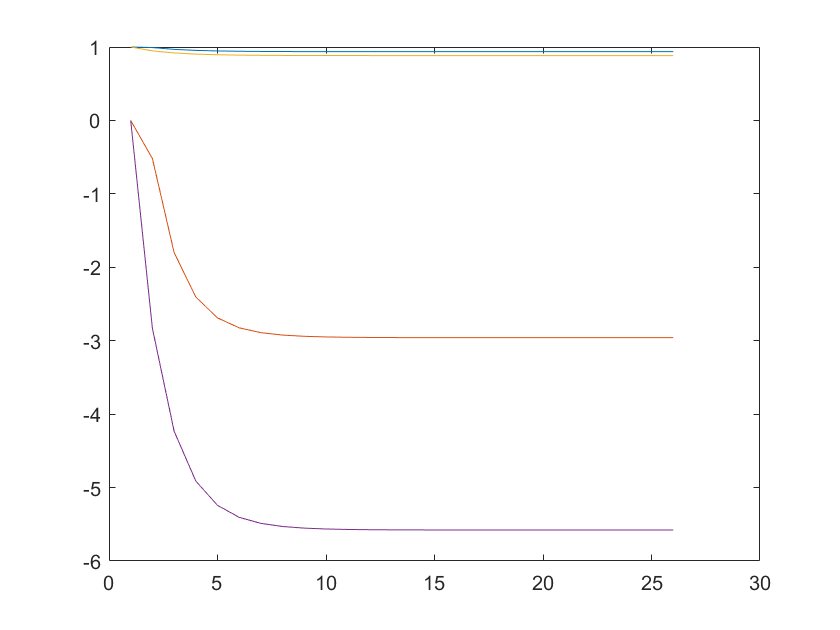


plot(Output)% plots the graph of gauss seidel

**Displaying Y matrix**

disp('____________________________________________________________')

____________________________________________________________


disp('                           Ymatrix');

                           Ymatrix


disp('____________________________________________________________')

____________________________________________________________


disp(y);

   1.9183 -16.4429i  -1.9183 +16.4429i   0.0000 + 0.0000i
  -1.9183 +16.4429i   3.3328 -30.5871i  -1.4144 +14.1443i
   0.0000 + 0.0000i  -1.4144 +14.1443i   1.4144 -14.1443i



**Displaying Power Vectors**

disp('_____________________________')

_____________________________


disp('     Power Vectors ')

     Power Vectors 


disp('_____________________________')

_____________________________


disp('      P        Q')

      P        Q


disp(S)

   0.9189 - 0.9717i
  -0.3000 - 0.2000i
  -0.6000 - 0.6000i



**Displaying Voltage vectors **

disp('_____________________________')

_____________________________


disp('    Voltage Vectors ')

    Voltage Vectors 


disp('_____________________________')

_____________________________


disp('    voltage   angle')

    voltage   angle


disp(V)

    1.0000         0
    0.9365   -2.9585
    0.8832   -5.5779



**Displaying power losses**

disp('_____________________________')

_____________________________


disp('        Power Losses')

        Power Losses


disp('_____________________________')

_____________________________


disp('Real Power loss     Reactive Power loss');

Real Power loss     Reactive Power loss


disp(losses)

2.0177                   -32.7138
